## Assignment-6b

#### **Companion Book MATLAB Problems (chapter3)**

### 3.1  Tutorial: Computing the Discrete-Time Fourier Series with* fft*

The discrete-time Fourier seriers (DTFS) is a frequency-domain representation for periodic discrete-time sequences.  For a signal x[n] with fundmental period N, the DTFS synthesis and analysis equations are given by:

$x[n] = \Sigma _{k=0} ^{N-1} a_k e^{jk(2\pi /N)n}$                                                                      (3.1)

$a_k = \frac 1 N \Sigma_{n=0}^{N-1}x[n]e^{-jk(2\pi/N)n} $                                                                (3.2)

For example, assume x[n] is the signal with fundamental period N=30.  The signal is given by

                                                            
$$x\left\lbrack n\right\rbrack =\left\lbrace \begin{array}{cc}
1 & n=0\;1\\
0 & \textrm{otherwise}
\end{array}\right.$$


on the interval $$0 \le n \le 29$$.  Plot x[n] over interval [0, N-1]

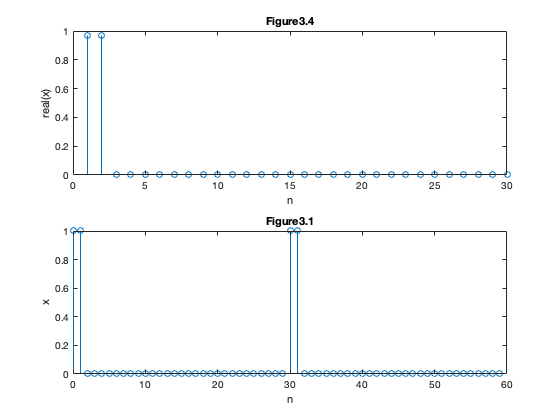

% 3.1 of companion book
N=30;
n1=[0:59];
x=[1 1 zeros(1,28)];
xn=[x x];

stem(n1,xn); xlabel('n');ylabel('x');title('Figure3.1');

Define *x = [1 1 zeros(1,28)*}.  The DTFS can be computed by typing *a = (1/N) * fft(x). The real and imaginary parts of a can be ploted as shown in Figures 3.2 and 3.3.*

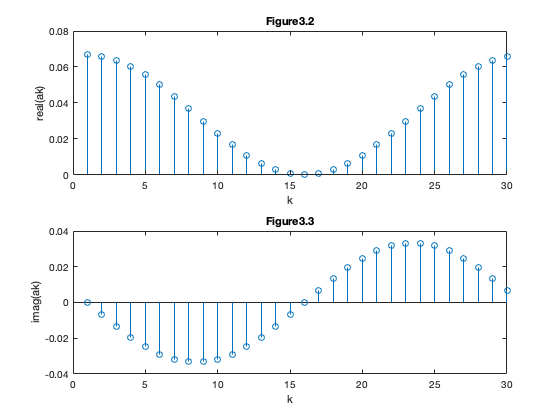


x=[1 1 zeros(1,28)];
ak= (1/N)*fft(x);
figure;
subplot(2,1,1);stem(real(ak));xlabel('k');ylabel('real(ak)');title('Figure3.2');
subplot(2,1,2);stem(imag(ak));xlabel('k');ylabel('imag(ak)');title('Figure3.3');

You can verify analytically that these are the correct valuse for $a_k$, as shown in Figure 3.2 and 3.3.

Given a vector *a* containing the DTFS coefficients $$a_k \ for \ 0 \le k \le N-1$$, the function ***ifft*** can be used to construct a vector ***x*** containing $$x[n] \ for \ 0 \le n \le N-1$$ as follows:

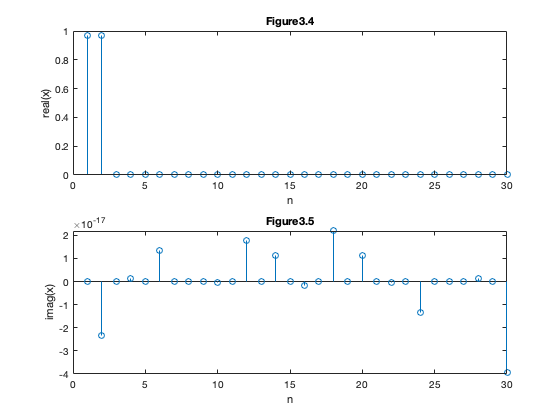

% use ifft()
clf;
x1= (N-1)*ifft(ak);
x2= (N-1)*ifft(imag(ak));
figure(1);
subplot(2,1,1);stem(x1);xlabel('n');ylabel('real(x)');title('Figure3.4');
subplot(2,1,2);stem(x2);xlabel('n');ylabel('imag(x)');title('Figure3.5');

Note that the imaginary component  is insignificant compared to the real component, so it was shown close to zero as shown in Figure 3.5.

#### 3.2  Tutorial: freqz

The signals $e^{jwn}$ are elements of LTI systems.  For each value of $\omega$ the frequency response $H(e^{jw}) $ is the eigenvalue of the LTI system for eigenfunction $e^{jwn}$; when the input sequence is $x[n]=e^{j \omega _0 n}$, the output sequence is $y[n]=H(e^{j\omega _0})e^{j\omega _0 n}$.   

(a).   Define a1 and b1 to describe the causal LTI system specified by the difference equation

        $$y[n] - 0.8y[n-1]=2x[n] - x[n-2]$$.  

b1=[2 0 -1]

b1 =      2     0    -1


a1=[1  -0.8]

a1 =     1.0000   -0.8000


(b).   Use ***freqz*** with the coefficients from Part (a) to define ***H1*** to be the value of the frequency response at 4 evenly spaced frequencies between 0 and $\pi$ and ***omeg1*** to be those frequencies.  The following sample output shows the values each vector should have if you have defined things correctly:      

[h1 w1]=freqz(b1,a1,4,"whole",pi)

h1 =    5.0000 + 0.0000i
   1.8293 - 1.4634i
   0.5556 + 0.0000i
   1.8293 + 1.4634i


w1 =          0
    0.7854
    1.5708
    2.3562


(c).   Use ***freqz*** to define ***H2*** to be the value of the frequency response at 4 evenly spaced frequencies between 0 and $2\pi$ and ***omega2*** to be those frequencies.  The following sample output shows the values each vector should have if you have defined things correctly:    

[h1 w1]=freqz(b1,a1,4,'whole',2*pi)

h1 =    5.0000 + 0.0000i
   1.8293 - 1.4634i
   0.5556 + 0.0000i
   1.8293 + 1.4634i


w1 =          0
    1.5708
    3.1416
    4.7124


#### 3.3  Tutorial: lsim with System Functions

As an example, consider the system function

                        
$$H(s) = \frac {s+ \frac 1 2} {s-2}$$


where coefficients are defined by the voctors $b=[1 \ 1/2] \ and \ a=[1 \  -2]$.  The command $y=lsim(b,a,x,t)$ stores in **y** the time response of the system to the input specified in the vector **x** at the times specified in **t**.  The vector** y** has as many elements as the input vector **x**.

(a). Define coefficient vectors **a1** and **b1** to describe the causal LTI system specified by the system function

                        
$$H_1(s) = \frac {s - 2} {s + 2}$$


b1=[1 -2]

b1 =      1    -2


a1=[1 2]

a1 =      1     2


(b). Define coefficient vectors a2 and b2 to describe the causal LTI system specified by the system function

                        
$$H_2(s) = \frac {3} {s + 0.3}$$


b2=[0 3]

b2 =      0     3


a2=[1 0.3]

a2 =     1.0000    0.3000


(c).  Define coefficient vectors a3 and b3 to describe the causal LTI system specified by the system function

                        
$$H_3(s) = \frac {2s} {s + 0.8}$$


b3=[2 0]

b3 =      2     0


a3=[1 0.8]

a3 =     1.0000    0.8000


(d). Use ***lsim*** and vectors  you defined in the previous parts to find the output of those causal LTI systems for the input given by ***t = [0:0.1:0.5], x=cos(t).*** The results shown below give the output for each system.

t=[0:0.1:0.5];
x=cos(t);

y1=lsim(b1,a1,x,t )

y1 =     1.0000
    0.6334
    0.3261
    0.0692
   -0.1444
   -0.3205



y2=lsim(b2,a2,x,t )

y2 =          0
    0.2948
    0.5779
    0.8468
    1.0991
    1.3323



y3=lsim(b3,a3,x,t )

y3 =     2.0000
    1.8366
    1.6667
    1.4910
    1.3105
    1.1262
